## Virtual City Testbed Water Distribution SCADA

clear
% Establish a connection with the simulation of the Backend Simulation Platform
S = KIOSBaSP()

S =   KIOSBaSP with properties:

    baseURL: "http://localhost:8000/api/"
        key: []


If the class is loaded, you should see the following response:

`S = `

  [`KIOSBaSP`](matlab:helpPopup KIOSBaSP)` with properties:`

`    baseURL: "http://localhost:8000/api/"`

`        key: []`

Load the GET/POST commands

S.WaterLoadGet

ans = "HTTP 200 OK"

S.WaterLoadPost

ans = "HTTP 200 OK"

Start the get API command

[status ~] = S.WaterStartGet

status = "HTTP 200 OK"

Load the configuration of the sensors

config = 'dataset_configuration.yaml';

Load data structure with sensors (specified by user in sensors.json file). For each sensor, we need to define a number of parameters related to its metadata (type, ID, minimum and maximum values, sampling resolution, uncertainty and distribution, location etc.

...{

"**sensorid**":"pressure_1", 

"**sensortype**":"pressure", 

"**nodelink**":"node", 

"**id**":"n1", 

"**min**":0.0, 

"**max**":100.0, 

"**resolution**":0.1, 

"**uncertainty**":5, 

"**uncertaintydist**":"uniform", 

"**lat**": 34.68618568144877, 

"**long**":33.03823996696676

},...

fileName = 'sensors.json' 

fileName = 'sensors.json'

sensors = fileread(fileName) % dedicated for reading files as text 

sensors =     '{"sensors": [
     	{"sensorid":"pressure_1", "sensortype":"pressure", "nodelink":"node", "id":"n1", "min":0.0, "max":100.0, "resolution":0.1, "uncertainty":5, "uncertaintydist":"uniform", "lat": 34.68618568144877, "long":33.03823996696676},
     	{"sensorid":"pressure_2", "sensortype":"pressure", "nodelink":"node", "id":"n4", "min":0.0, "max":100.0, "resolution":0.1, "uncertainty":5, "uncertaintydist":"uniform", "lat": 34.6846624641005, "long":33.039913454810005},
     	{"sensorid":"pressure_3", "sensortype":"pressure", "nodelink":"node", "id":"n31", "min":0.0, "max":100.0, "resolution":0.1, "uncertainty":5, "uncertaintydist":"uniform", "lat": 34.68368626984823, "long":33.042798392447594},
     	{"sensorid":"pressure_4", "sensortype":"pressure", "nodelink":"node", "id":"n54", "min":0.0, "max":100.0, "resolution":0.1, "uncertainty":5, "uncertaintydist":"uniform", "lat": 34.685040705456785, "long":33.045131897373714},
     	{"sensorid":"pressure_5", "sensortype":"pressure

data = jsondecode(sensors) % create data structure

data = struct with fields:
    sensors: [51×1 struct]


Set the simulation metadata

fromD = datetime(2023,03,20)

fromD = datetime
   20-Mar-2023


toD = datetime(2023,03,22)

toD = datetime
   22-Mar-2023


startDate = datestr(fromD,'yyyy-mm-dd')

startDate = '2023-03-20'

endDate = datestr(toD,'yyyy-mm-dd')

endDate = '2023-03-22'

expiramentname= char(randi([97 122],1,5)) % create random experiment name

expiramentname = 'rawyr'

Run the experiment

[status,response] = S.WaterAddLeakViewSetPost(config)

status = "HTTP 200 OK"

response = 'Done'


S.WaterStartWNTRPost(startDate,endDate,expiramentname,fileName,config)

ans = "HTTP 200 OK"

%S.WaterStartPost(startDate, endDate, expiramentname,fileName)

Get the sensor data

[status, sensordata] = S.WaterOutputSensorsPost(expiramentname,'')

status = "HTTP 200 OK"

sensordata = 51×1 struct array with fields:
    sensorid
    values


Datetime={sensordata(1).values.timestamp}';
Datetime=datetime(Datetime, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss''Z');
SensorID={sensordata.sensorid}';

presInd_TS = find(contains(SensorID,'pressure'));
AMRInd_TS = find(contains(SensorID,'demand'));
FlowInd_TS = find(contains(SensorID,'flow'));
levelInd_TS=find(contains(SensorID,'level'));
reservoirInd_TS=find(contains(SensorID,'reservoir'));

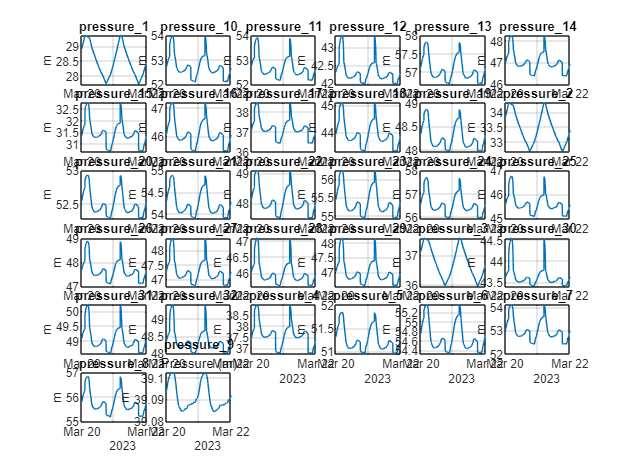

dim = ceil(sqrt(length(presInd_TS)));
figure
for i = 1:length(presInd_TS)
    pressure(:,i) = cell2mat({sensordata(presInd_TS(i)).values.value});
    subplot(dim,dim,i)
    plot(Datetime,pressure(:,i))
    title(['',SensorID{presInd_TS(i)},''], 'Interpreter', 'none')
    ylabel('m')
    grid on
end
subtitle('Pressure (m)')